# Summary of Alpha Values from VBWIM

% Search through VBResults and gather all 'All' alpha values! Scatter plot
clear, clc, close all

D = linspecer(30);  
%load('VBResultsAlpha60t.mat')
%load('VBResultsAlphaq(Q1=06etQ2=04)NEWLucas.mat')
load('VBResultsWIMDDR020323prBeta4_2_50m.mat')
Model = "SIA";
BlockM = "Weekly";
%if strcmp(Model,"ESIA")
  %VBR = VBResults.Monthly;
%else
%Model = "ESIA";
VBR = VBResults.(Model).(BlockM);
%VBR = VBResults.(append('E',Model)).(BlockM);
%VBR = VBResults.(Model).(BlockM);
VBRDet = VBR(VBR.Traffic == 'Deterministic',:);
VBR = VBR(VBR.Traffic ~= 'Deterministic',:);
%end
%load('VBResultsSimNov4Jam2pourc_pr.mat')
%VBR.ClassOW = VBResults.(Model).(BlockM).Class;

VBR(VBR.Span == 2,:) = []; % remove 2 meters span
VBRDet(VBRDet.Span == 2,:) = []; % remove 2 meters span
%VBR(VBR.AE == "MxEdg" | VBR.AE == "MxMid",:) = []; % remove MxMid MxEdg from Slab
%VBR(VBR.Type == "Slab",:) = []; % remove Slab
VBR(VBR.Type == "Twin" & VBR.Span == 10,:) = []; % remove 10 meters Twin
St = [4 6 8 10 15 20 25 30 40 50 60 70 80]; % no 2 meters
%St = [1.22 2.33 3 3.44 4.56 5.67 6.78 7.5 12]; %
%St = [4 5 6 8 10 15 20 25 30 40 50 60 70 80]; % no 2 meters
%St = [20 30 40 50 60 70 80]; % no 2 meters
Lab = {'4', '6', '8', '10', '15', '20', '25', '30', '40', '50', '60', '70', '80'}; % no 2 meters
%Lab = {'1.22', '2.33', '3', '3.44', '4.56', '5.67', '6.78', '7.5', '12'}; %
%Lab = {'4', '5', '6', '8', '10', '15', '20', '25', '30', '40', '50', '60', '70', '80'}; % no 2 meters
%Lab = {'20', '30', '40', '50', '60', '70', '80'}; % no 2 meters
Fi = [1 2 3 4 5  6  7  8  9  10 11 12 13]; % no 2 meters
%Fi = [1 2 3 4 5  6  7  8  9];
%Fi = [1 2 3 4 5  6  7 ]; % no 2 meters

[~, idx] = ismember(VBR.Span,St);
xdataTr = Fi(idx);
[~, idxDet] = ismember(VBRDet.Span,St);
xdataTrDet = Fi(idxDet);
if size(xdataTrDet,2)>=1
    DoDet = 1;
else
    DoDet = 0;
end

## Main Plot

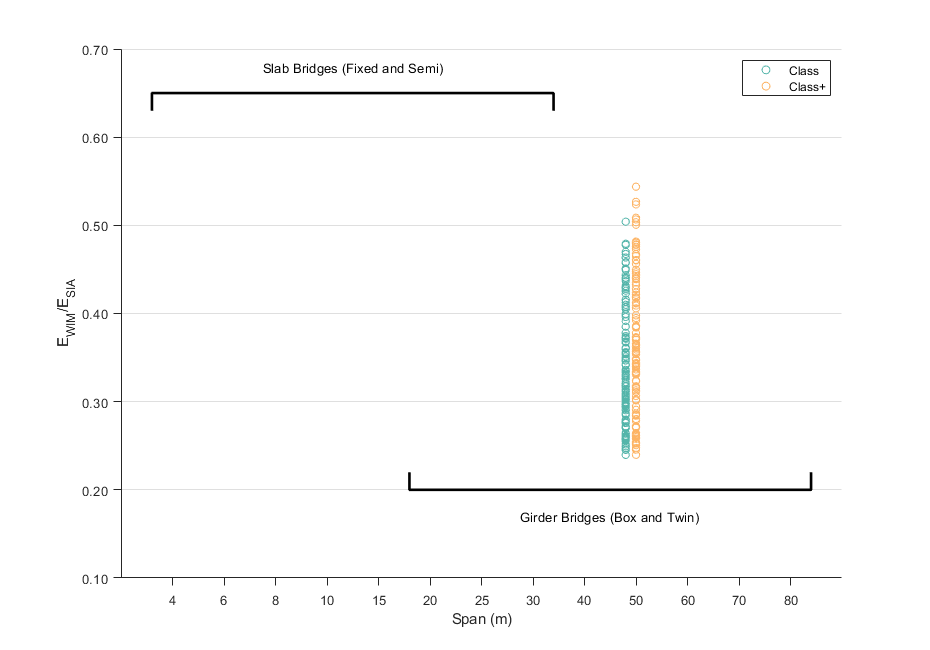

figure('Position',[325 225 930 650]); hold on;
%scatter(xdataTrSS+0.2,VBResults.SS.(BlockM).All./1.15,30,[0.8 0.8 0.8],'DisplayName','StopSim');
%scatter(xdataTrSS,VBResults.SS.(BlockM).ClassOW./1.15,30,[0.8 0.8 0.8],'HandleVisibility','off');
%scatter(xdataTrSS-0.2,VBResults.SS.(BlockM).Class./1.15,30,[0.8 0.8 0.8],'HandleVisibility','off');

PlClass=scatter(xdataTr-0.2,VBR.Class,30,D(6,:),'DisplayName','Class');
PlClassOW=scatter(xdataTr,VBR.ClassOW,30,D(21,:),'DisplayName','Class+');
%PlClass=scatter(xdataTr-0.2,VBR.Class,30,D(6,:),'DisplayName','Jammed 1%');
%PlClassOW=scatter(xdataTr,VBR.ClassOW,30,D(21,:),'DisplayName','Jammed 2%');
%PlClassOW=scatter(xdataTr,VBR.ClassOW,30,D(21,:),'DisplayName','Class+ Accompaniment (can be all)');
if DoDet 
    PlDeter=scatter(xdataTrDet+0.2,VBRDet.Class,30,D(3,:),'DisplayName','Deterministic');
end
%scatter(xdataTr-0.2,VBR.ClassOW,30,D(6,:),'DisplayName','Class+ Accompaniment');
%scatter(xdataTr,VBR.ClassOW,30,D(21,:),'DisplayName','% of q in ESIA');
%scatter(xdataTr(VBR.Type=="Box")-0.2,VBR.PropTrucks(VBR.Type=="Box").*100,30,D(6,:),'DisplayName','Box');
%scatter(xdataTr(VBR.Type=="Slab"),VBR.PropTrucks(VBR.Type=="Slab").*100,30,D(21,:),'DisplayName','Slab');
%scatter(xdataTr(VBR.Type=="Twin" & VBR.Span~=10)+0.2,VBR.PropTrucks(VBR.Type=="Twin" & VBR.Span~=10).*100,30,D(1,:),'DisplayName','Twin');
%{
load('VBResultsAlphaQ2.mat');
if strcmp(Model,"ESIA")
    VBR2 = VBResults.(BlockM);
else
    VBR2 = VBResults.(Model).(BlockM);
end
VBR2(VBR2.Span == 2,:) = [];
VBR2(VBR2.Type == "Twin" & VBR2.Span == 10,:) = [];
[~, idx2] = ismember(VBR2.Span,St);
xdataTr2 = Fi(idx2);
%s = scatter(xdataTr2+0.45,VBR2.All,30,D(1,:)+[0.3 0.3 0.3],"filled",'DisplayName','All LogNormal Fitting');
%s.MarkerFaceAlpha = 0.6;
%s = scatter(xdataTr2+0.15,VBR2.ClassOW,30,D(21,:)+[0.0 0.2 0.3],"filled",'DisplayName','Class+ LogNormal Fitting');
%s.MarkerFaceAlpha = 0.6;
s = scatter(xdataTr2,VBR2.ClassOW,30,D(21,:),'DisplayName','All Accompaniment');
s.MarkerFaceAlpha = 0.6;
%s = scatter(xdataTr2-0.15,VBR2.Class,30,D(6,:)+[0.25 0.15 0.1],"filled",'DisplayName','Class LogNormal Fitting');
%s.MarkerFaceAlpha = 0.6;
%}

xlim([0 max(Fi) + 1]); 
ylim([0.1 0.7])
%ylim([2.5 3.5])
%ylim([0 100])

ytickformat('%.2f');
%ytickformat('percentage');
yticks(0.1:0.1:0.7);
%yticks(2.5:0.1:3.5);
%yticks(0:10:100);
set(gca,'TickDir','out');
set(gca,'YGrid','on');
xticks(Fi);
xticklabels(Lab);
xlabel('Span (m)')
%xlabel('Largeur (m)')
%title('Monthly Block Maxima Summary')
ylabel(append('E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('E_{SIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('E_{qSIA}/E_{WIM}'))
%ylabel(append('E_{qSIA}/E_{(Q1+Q2+q)SIA}'))
%ylabel(append('\fontsize{16} \bf\alpha_{Q2} \fontsize{11} \rm (with \alpha_{Q1} = 0 and \alpha_{q} = 0.5)        E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('\fontsize{16} \bf\alpha_{q} \fontsize{11} \rm (with \alpha_{Q1} = 0.55 and \alpha_{Q2} = 0.35)        E_{SIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('% of Special Transport Monthly Maxima with Accompaniment'))
%legend('location','southwest')
legend('location','northeast')

% for finding the Infl Name
SpanName = int2str(VBR.Span);
SpanName((SpanName(:,1)==' '),1) = '0';
SpanName = strcat('S',SpanName);
InflName = VBR.Type + '.' + VBR.SubType + '.' + VBR.Width + '.' + VBR.Layout + '.' + VBR.Support + '.' + VBR.Trans + '.' + VBR.AE + '.' + SpanName;
row = dataTipTextRow('Infl',InflName);
PlClass.DataTipTemplate.DataTipRows(end+1) = row;
try PlClassOW.DataTipTemplate.DataTipRows(end+1) = row; catch end
PlClass.DataTipTemplate.DataTipRows(1).Value = VBR.Span;
try PlClassOW.DataTipTemplate.DataTipRows(1).Value = VBR.Span; catch end

if DoDet
SpanNameDet = int2str(VBRDet.Span);
SpanNameDet((SpanNameDet(:,1)==' '),1) = '0';
SpanNameDet = strcat('S',SpanNameDet);
InflNameDet = VBRDet.Type + '.' + VBRDet.SubType + '.' + VBRDet.Width + '.' + VBRDet.Layout + '.' + VBRDet.Support + '.' + VBRDet.Trans + '.' + VBRDet.AE + '.' + SpanNameDet;
rowdet = dataTipTextRow('Infl',InflNameDet);
PlDeter.DataTipTemplate.DataTipRows(end+1) = rowdet;
PlDeter.DataTipTemplate.DataTipRows(1).Value = VBRDet.Span;
end

% for Ebru comparison
%ylucas = [1.68,1.98,1.57,1.75,1.83,1.87,1.86,1.82,1.74,1.31,1.21,1.12,1.09,1.07];
%ylucas = [1.98,1.57,1.75,1.83,1.87,1.86,1.82,1.74,1.31,1.21,1.12,1.09,1.07];
%ylucas2 = [1.38,1.84,1.52,1.77,1.85,1.90,1.87,1.84,1.76,1.27,1.16,1.04,0.95,0.87];
%ylucas2 = [1.84,1.52,1.77,1.85,1.90,1.87,1.84,1.76,1.27,1.16,1.04,0.95,0.87];
%plot(Fi,ylucas,'Color',D(1,:),'LineStyle',"--","LineWidth",1,'DisplayName','OriginalAll');
%plot(Fi,ylucas2,'Color',D(21,:),'LineStyle',"--","LineWidth",1,'DisplayName','OriginalClass+');

%{%
yh = 0.65; %0.85
line([0.6,0.6,8.4,8.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
%line([0.6,0.6,2.4,2.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
%line([3.6,3.6,7.4,7.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
text(4.5,yh+0.03,'Slab Bridges (Fixed and Semi)','HorizontalAlignment','center')
%text(3.0,yh+0.03,'Porte-à-faux','HorizontalAlignment','center')
yh = 0.20; %0.15
line([5.6,5.6,13.4,13.4],[yh+0.02,yh,yh,yh+0.02],'Color','k','LineWidth',2,'HandleVisibility','off')
%line([2.58,2.58,3.2,3.2],[yh+0.02,yh,yh,yh+0.02],'Color','r','LineWidth',2,'HandleVisibility','off')
%line([7.6,7.6,9.2,9.2],[yh+0.02,yh,yh,yh+0.02],'Color','r','LineWidth',2,'HandleVisibility','off')
text(9.5,yh-0.03,'Girder Bridges (Box and Twin)','HorizontalAlignment','center')

%text(5.4,yh-0.03,'Dalle entre poutres','Color','r','HorizontalAlignment','center')
%}


## Selectable Plot

% Refine VBR Based on checkboxes
LBox = VBR.Type == 'Box';
LTwin = VBR.Type == 'Twin';
LSlab = VBR.Type == 'Slab';
LMulti = VBR.Type == 'Multi';

LMp = VBR.AE == 'Mp';
LMn = VBR.AE == 'Mn';
LV = VBR.AE == 'V';
LMxEdg = VBR.AE == 'MxEdg';
LMxMid = VBR.AE == 'MxMid';

Lp0 = VBR.Trans == 'p0';
Lp1 = VBR.Trans == 'p1';
Lp2 = VBR.Trans == 'p2';
Lp3 = VBR.Trans == 'p3';

LUni2L = VBR.Traffic == 'Uni2L';
LBi2L = VBR.Traffic == 'Bi2L';
LBi4L = VBR.Traffic == 'Bi4L';

if DoDet
LBoxDet = VBRDet.Type == 'Box';
LTwinDet = VBRDet.Type == 'Twin';
LSlabDet = VBRDet.Type == 'Slab';
LMultiDet = VBRDet.Type == 'Multi';

LMpDet = VBRDet.AE == 'Mp';
LMnDet = VBRDet.AE == 'Mn';
LVDet = VBRDet.AE == 'V';
LMxEdgDet = VBRDet.AE == 'MxEdg';
LMxMidDet = VBRDet.AE == 'MxMid';

Lp0Det = VBRDet.Trans == 'p0';
Lp1Det = VBRDet.Trans == 'p1';
Lp2Det = VBRDet.Trans == 'p2';
Lp3Det = VBRDet.Trans == 'p3';

end


### Type

Box = false;
Twin = false;
Slab = false;
Multi = false;

% Update logical
Log = any([Box*LBox Twin*LTwin Slab*LSlab Multi*LMulti],2);
% Combine Logicals to get master logical
if DoDet
%xd = xdataTr(Log) + 0.2;
LogDet = any([Box*LBoxDet Twin*LTwinDet Slab*LSlabDet Multi*LMultiDet],2);
xdDet = xdataTrDet(LogDet) + 0.2;
VBRPlot = VBRDet.Class(LogDet);
try delete(h1); end
h1 = scatter(xdDet,VBRPlot,30,'k','filled','DisplayName','Selection');
end
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Action Effect

Mn = false;
Mp = false;
V = false;
MxEdg = false;
MxMid = false;

% Update logical
Log = any([Mn*LMn Mp*LMp V*LV MxEdg*LMxEdg MxMid*LMxMid],2);
% Combine Logicals to get master logical
%xd = xdataTr(Log) + 0.2;
if DoDet
LogDet = any([Mn*LMnDet Mp*LMpDet V*LVDet MxEdg*LMxEdgDet MxMid*LMxMidDet],2);
xdDet = xdataTrDet(LogDet) + 0.2;
%VBRPlot = VBR.All(Log);
VBRPlot = VBRDet.Class(LogDet);
try delete(h1); end
h1 = scatter(xdDet,VBRPlot,30,'k','filled','DisplayName','Selection');
end
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Transverse Location

p0 = false;
p1 = false;
p2 = false;
p3 = false;

% Update logical
Log = any([p0*Lp0 p1*Lp1 p2*Lp2 p3*Lp3],2);
% Combine Logicals to get master logical
%xd = xdataTr(Log) + 0.2;
if DoDet
LogDet = any([p0*Lp0Det p1*Lp1Det p2*Lp2Det p3*Lp3Det],2);
xdDet = xdataTrDet(LogDet) + 0.2;
%VBRPlot = VBR.All(Log);
VBRPlot = VBRDet.Class(LogDet);
try delete(h1); end
h1 = scatter(xdDet,VBRPlot,30,'k','filled','DisplayName','Selection');
end
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Transverse Location

Uni2L = false;
Bi2L = false;
Bi4L = false;

% Update logical
Log = any([Uni2L*LUni2L Bi2L*LBi2L Bi4L*LBi4L],2);
% Combine Logicals to get master logical
xd = xdataTr(Log) + 0.2;
VBRPlot = VBR.All(Log);
try delete(h1); end
%h1 = scatter(xd,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Show Probability Paper Plot + Distribution + Worst Cases : When clicked on plot

ClickOption =  false;
NumberofCases = 5;
%OutputFolder = "WIMOct5Redopr";
try OutputFolder = VBResults.FolderName; catch end
DistTypes = "All";
Dyna = false;

if ClickOption
aH = gca;
sizeplot.x = aH.XTick;
sizeplot.xlength = sizeplot.x(end)-sizeplot.x(1);
sizeplot.xlimorig = xlim;
sizeplot.y = aH.YTick;
sizeplot.ylength = sizeplot.y(end)-sizeplot.y(1);
sizeplot.ylimorig = ylim;
xd = [];
Log = false(size(VBR,1),1);
VBRPlot = VBR.All(Log);
try delete(h1); end
h1 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
Allpoints = [(xdataTr-0.2)',VBR.Class,ones(size(VBR.Class,1),1),(1:size(VBR.Class,1))';xdataTr',VBR.ClassOW,2*ones(size(VBR.ClassOW,1),1),(1:size(VBR.ClassOW,1))';(xdataTrDet+0.2)',VBRDet.Class,3*ones(size(VBRDet.Class,1),1),(1:size(VBRDet.Class,1))'];
[button.x,button.y,button.clic] = ginput(1);
xlim([button.x-0.05.*sizeplot.xlength button.x+0.05.*sizeplot.xlength]);
ylim([button.y-0.05.*sizeplot.ylength button.y+0.05.*sizeplot.ylength]);
Allpoints(Allpoints(:,1)<button.x-0.05.*sizeplot.xlength,:) = [];
Allpoints(Allpoints(:,1)>button.x+0.05.*sizeplot.xlength,:) = [];
Allpoints(Allpoints(:,2)<button.y-0.05.*sizeplot.ylength,:) = [];
Allpoints(Allpoints(:,2)>button.y+0.05.*sizeplot.ylength,:) = [];
for i=1:size(Allpoints,1)
    if Allpoints(i,3)==3
        text(Allpoints(i,1)+0.002.*sizeplot.xlength,Allpoints(i,2),[InflNameDet(Allpoints(i,4))])
    else
        text(Allpoints(i,1)+0.002.*sizeplot.xlength,Allpoints(i,2),[InflName(Allpoints(i,4))])
    end
end
[button.x,button.y,button.clic] = ginput(1);
[button.number,button.dist] = dsearchn(Allpoints(:,1:2),[button.x,button.y]);
SelectedPoint.info = Allpoints(button.number,:);
if SelectedPoint.info(1,3)==3
    SelectedPoint.infl = InflNameDet(SelectedPoint.info(1,4));
else
    SelectedPoint.infl = InflName(SelectedPoint.info(1,4));
end
SelectedPoint.infl = convertStringsToChars(SelectedPoint.infl);
SelectedPoint.infl = append(SelectedPoint.infl(1:end-2),num2str(str2num(SelectedPoint.infl(end-1:end))));
SelectedPoint.xbox = xlim;
SelectedPoint.xtext = (SelectedPoint.xbox(end)+SelectedPoint.xbox(1))./2-0.35.*(SelectedPoint.xbox(end)-SelectedPoint.xbox(1));
SelectedPoint.ybox = ylim;
SelectedPoint.ytext = (SelectedPoint.ybox(end)+SelectedPoint.ybox(1))./2;
SelectedPoint.class = {'Class','ClassOW','All'};
SelectedPoint.class = SelectedPoint.class{SelectedPoint.info(1,3)};
plot(SelectedPoint.info(1,1),SelectedPoint.info(1,2),'b*','MarkerSize',20,'DisplayName','Selection','LineWidth',2);
SelectedPoint.text = text(SelectedPoint.xtext,SelectedPoint.ytext,'RUNNING! PLEASE WAIT...','Color','red','FontSize',30);
%run the thing here
pause(3)
close all
PeekatResults(SelectedPoint.infl,OutputFolder,BlockM,SelectedPoint.class,DistTypes,NumberofCases,Dyna)
%set(gcf,'Visible','on')
%run the thing here
%delete(SelectedPoint.text);
%xlim(sizeplot.xlimorig);
%ylim(sizeplot.ylimorig);
end

### Colors for Best Fits

ColorPlot = false;

if ColorPlot
clf

%try delete(h1); end
%h1 = scatter([],[],30,'k','filled','HandleVisibility','off');
%try delete(h2); end
%h2 = scatter([],[],30,'k','filled','HandleVisibility','off');
%try delete(h3); end
%h3 = scatter([],[],30,'k','filled','HandleVisibility','off');

scatter(xdataTr(VBR.BestFitClassOW=='Lognormal'),VBR.ClassOW(VBR.BestFitClassOW=='Lognormal'),30,D(13,:),'filled','DisplayName','Class+ Lognormal');
hold on;
scatter(xdataTr(VBR.BestFitClassOW=='LognormalTF'),VBR.ClassOW(VBR.BestFitClassOW=='LognormalTF'),30,D(10,:),'filled','DisplayName','Class+ LognormalTF');
scatter(xdataTr(VBR.BestFitClassOW=='Normal'),VBR.ClassOW(VBR.BestFitClassOW=='Normal'),30,D(7,:),'filled','DisplayName','Class+ Normal');
scatter(xdataTr(VBR.BestFitClassOW=='gev'),VBR.ClassOW(VBR.BestFitClassOW=='gev'),30,D(4,:),'DisplayName','Class+ gev');
scatter(xdataTr(VBR.BestFitClassOW=='gevGumbel'),VBR.ClassOW(VBR.BestFitClassOW=='gevGumbel'),30,D(1,:),'DisplayName','Class+ gevGumbel');
%scatter(xdataTr-0.2,VBR.ClassOW,30,D(6,:),'DisplayName','Class+ Accompaniment');
scatter(xdataTr(VBR.BestFitClass=='Lognormal')-0.2,VBR.Class(VBR.BestFitClass=='Lognormal'),30,D(18,:),'filled','DisplayName','Class Lognormal');
scatter(xdataTr(VBR.BestFitClass=='LognormalTF')-0.2,VBR.Class(VBR.BestFitClass=='LognormalTF'),30,D(21,:),'filled','DisplayName','Class LognormalTF');
scatter(xdataTr(VBR.BestFitClass=='Normal')-0.2,VBR.Class(VBR.BestFitClass=='Normal'),30,D(24,:),'filled','DisplayName','Class Normal');
scatter(xdataTr(VBR.BestFitClass=='gev')-0.2,VBR.Class(VBR.BestFitClass=='gev'),30,D(27,:),'DisplayName','Class gev');
scatter(xdataTr(VBR.BestFitClass=='gevGumbel')-0.2,VBR.Class(VBR.BestFitClass=='gevGumbel'),30,D(30,:),'DisplayName','Class gevGumbel');
xlim([0 max(Fi) + 1]); 
ylim([0.0 1.0])
%ylim([0 100])

ytickformat('%.2f');
%ytickformat('percentage');
yticks(0.0:0.1:1.0);
%yticks(0:10:100);
set(gca,'TickDir','out');
set(gca,'YGrid','on');
xticks(Fi);
xticklabels(Lab);
xlabel('Span (m)')
%title('Monthly Block Maxima Summary')
ylabel(append('E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('E_{qSIA}/E_{WIM}'))
%ylabel(append('E_{qSIA}/E_{(Q1+Q2+q)SIA}'))
%ylabel(append('\fontsize{16} \bf\alpha_{Q2} \fontsize{11} \rm (with \alpha_{Q1} = 0 and \alpha_{q} = 0.5)        E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('\fontsize{16} \bf\alpha_{Q2} \fontsize{11} \rm (with \alpha_{Q1} = 0 and \alpha_{q} = 0.5)        E_{WIM}/E_{SPTR}'))
%ylabel(append('% of Special Transport Monthly Maxima with Accompaniment'))
%legend('location','southwest')
legend('location','northeast')

yh = 0.7; %0.85
line([0.6,0.6,8.4,8.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
text(4.5,yh+0.03,'Slab Bridges (Fixed and Semi)','HorizontalAlignment','center')
yh = 0.10; %0.15
line([5.6,5.6,13.4,13.4],[yh+0.02,yh,yh,yh+0.02],'Color','k','LineWidth',2,'HandleVisibility','off')
text(9.5,yh-0.03,'Girder Bridges (Box and Twin)','HorizontalAlignment','center')
end

### Plots PUN Dalles de roulement

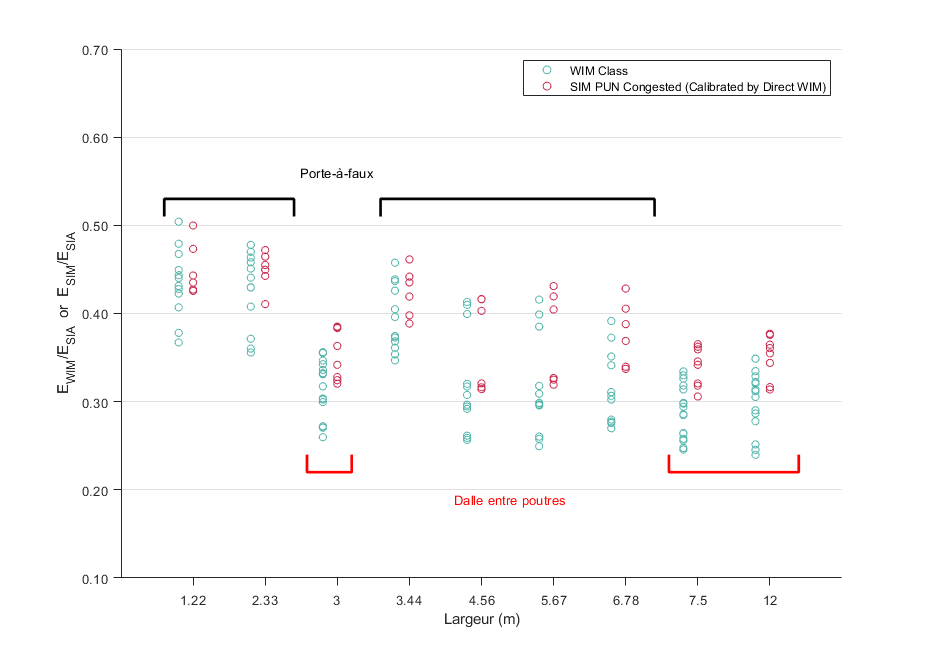

PUNDalR = true;

if PUNDalR
clf

load('VBResultsWIMDDR020323prBeta4_2.mat')
Model = "SIA";
BlockM = "Weekly";
VBR = VBResults.(Model).(BlockM);

%load('VBResultsSimMar10DallesRPUN2prBeta4_2.mat')
load('VBResultsSimMar10DallesRPUN2onlyConjprBeta4_2.mat')
VBR2 = VBResults.(Model);
%VBR3 = VBR2(strcmp(VBR2.Traffic,'PUN3LSimJam'),:);
VBR2 = VBR2(strcmp(VBR2.Traffic,'PUN3LSimConjCorr'),:);

St = [1.22 2.33 3 3.44 4.56 5.67 6.78 7.5 12]; %
Lab = {'1.22', '2.33', '3', '3.44', '4.56', '5.67', '6.78', '7.5', '12'}; %
Fi = [1 2 3 4 5  6  7  8  9];

[~, idx] = ismember(VBR.Span,St);
xdataTr = Fi(idx);
[~, idx2] = ismember(VBR2.Span,St);
xdataTr2 = Fi(idx2);
%[~, idx3] = ismember(VBR3.Span,St);
%xdataTr3 = Fi(idx3);

figure('Position',[325 225 930 650]); hold on;

PlClass=scatter(xdataTr-0.2,VBR.Class,30,D(6,:),'DisplayName','WIM Class');
PlClassOW=scatter(xdataTr2,VBR2.Class,30,D(28,:),'DisplayName','SIM PUN Congested (Calibrated by Direct WIM)');
%PlAll=scatter(xdataTr3+0.2,VBR3.Class,30,D(1,:),'DisplayName','SIM PUN Jammed');

xlim([0 max(Fi) + 1]); 
ylim([0.1 0.7])

ytickformat('%.2f');
yticks(0.1:0.1:0.7);
set(gca,'TickDir','out');
set(gca,'YGrid','on');
xticks(Fi);
xticklabels(Lab);
%xlabel('Span (m)')
xlabel('Largeur (m)')
ylabel(append('E_{WIM}/E_{',erase(Model,'E'),'}  or  E_{SIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('E_{SIM}/E_{',erase(Model,'E'),'}'))
legend('location','northeast')

% for finding the Infl Name
SpanName = int2str(VBR.Span);
SpanName((SpanName(:,1)==' '),1) = '0';
SpanName = strcat('S',SpanName);
InflName = VBR.Type + '.' + VBR.SubType + '.' + VBR.Width + '.' + VBR.Layout + '.' + VBR.Support + '.' + VBR.Trans + '.' + VBR.AE + '.' + SpanName;
row = dataTipTextRow('Infl',InflName);
PlClass.DataTipTemplate.DataTipRows(end+1) = row;
PlClass.DataTipTemplate.DataTipRows(1).Value = VBR.Span;

SpanName2 = int2str(VBR2.Span);
SpanName2((SpanName2(:,1)==' '),1) = '0';
SpanName2 = strcat('S',SpanName2);
InflName2 = VBR2.Type + '.' + VBR2.SubType + '.' + VBR2.Width + '.' + VBR2.Layout + '.' + VBR2.Support + '.' + VBR2.Trans + '.' + VBR2.AE + '.' + SpanName2;
row2 = dataTipTextRow('Infl',InflName2);
PlClassOW.DataTipTemplate.DataTipRows(end+1) = row2;
PlClassOW.DataTipTemplate.DataTipRows(1).Value = VBR2.Span;

%{
SpanName3 = int2str(VBR3.Span);
SpanName3((SpanName3(:,1)==' '),1) = '0';
SpanName3 = strcat('S',SpanName3);
InflName3 = VBR3.Type + '.' + VBR3.SubType + '.' + VBR3.Width + '.' + VBR3.Layout + '.' + VBR3.Support + '.' + VBR3.Trans + '.' + VBR3.AE + '.' + SpanName3;
row3 = dataTipTextRow('Infl',InflName3);
PlAll.DataTipTemplate.DataTipRows(end+1) = row3;
PlAll.DataTipTemplate.DataTipRows(1).Value = VBR3.Span;
%}

yh = 0.53; %0.85
%line([0.6,0.6,8.4,8.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
line([0.6,0.6,2.4,2.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
line([3.6,3.6,7.4,7.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
%text(4.5,yh+0.03,'Slab Bridges (Fixed and Semi)','HorizontalAlignment','center')
text(3.0,yh+0.03,'Porte-à-faux','HorizontalAlignment','center')
yh = 0.22; %0.15
%line([5.6,5.6,13.4,13.4],[yh+0.02,yh,yh,yh+0.02],'Color','k','LineWidth',2,'HandleVisibility','off')
line([2.58,2.58,3.2,3.2],[yh+0.02,yh,yh,yh+0.02],'Color','r','LineWidth',2,'HandleVisibility','off')
line([7.6,7.6,9.4,9.4],[yh+0.02,yh,yh,yh+0.02],'Color','r','LineWidth',2,'HandleVisibility','off')
%text(9.5,yh-0.03,'Girder Bridges (Box and Twin)','HorizontalAlignment','center')
text(5.4,yh-0.03,'Dalle entre poutres','Color','r','HorizontalAlignment','center')

end